**Split Line Plot with NaN Values **

**Creating a Split Line Plot with Gaps Using NaN Values**

When I work on visualizing data, I always aim to make my plots not only informative but also visually engaging. For this project, I decided to create a split line plot, incorporating NaN values to introduce intentional gaps in the lines. My goal was to explore how missing data could be effectively visualized and to customize the plot to make it both professional and visually appealing.

The first step was to define the x-values for two separate lines. I structured the data as a matrix, where each column represented a distinct line. This setup allowed me to easily manipulate each line individually. To introduce a gap in one of the lines, I inserted a NaN value at the third point of the second line. This was a deliberate choice to simulate a real-world scenario where data might be missing or unavailable.

Once the data was ready, I moved on to the visualization. For me, the aesthetics of a plot are just as important as the data it conveys. I created a new figure and used the `hold on` command to overlay multiple lines on the same plot.

For the first line, I chose a blue color (`#1f77b4`) and added circular markers to highlight each data point. For the second line, I selected an orange color (`#ff7f0e`) with square markers to create a clear visual distinction between the two lines. Adding these markers not only made the plot more engaging but also helped emphasize the data points, even in the presence of gaps.

I believe every plot should tell a story. To achieve this, I added a bold title to draw attention and set the context for the visualization: "Split Line Plot with NaN Values." I also labeled the x-axis and y-axis to clarify what the plot represents, making it easier for viewers to interpret the data. Including a grid was another crucial step, as it improved the overall readability by aligning the data points with the axes.

To ensure the plot was user-friendly, I added a legend to differentiate between the two lines. I positioned it in the top-left corner, which I found to be an intuitive spot for viewers to locate it. Additionally, I customized the axis properties to give the plot a polished appearance. Increasing the font size made the labels easier to read, and adding a box around the plot gave it a neat, professional finish.

This mini project helped reinforced my understanding of how small customizations can make a significant difference in the effectiveness of a plot. The use of NaN values to introduce gaps demonstrated how missing data could be visually represented without compromising the integrity of the plot. By focusing on design elements like colors, markers, and labels, I was able to create a visualization that was both aesthetically pleasing and informative.

For me, creating this plot was not just about the technical aspects—it was about making the data accessible and engaging. By combining thoughtful data representation with visual appeal, I achieved a plot that successfully communicated the story behind the data. This approach will undoubtedly guide my future visualization projects, especially when dealing with missing or incomplete datasets.

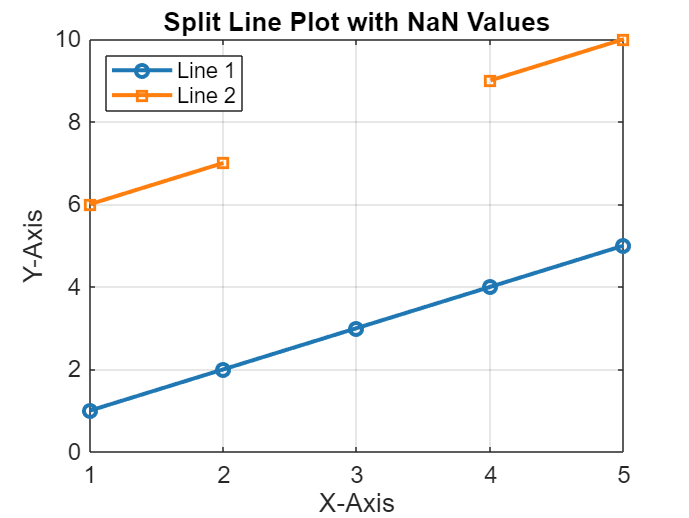

% Section 12.1: Split line with NaNs
% I want to create a split line plot with some NaN values to create gaps in the lines.
% I will customize the colors and add markers to make it look more professional and interesting.

% Step 1: Define x values
% I started by defining the x values for two separate lines.
% I then introduced a NaN value to create a break in one of the lines.
x = [1:5; 6:10]'; % I made a matrix where each column represents a line.
x(3, 2) = NaN;    % I added a NaN to break the second line at the third point.

% Step 2: Create the plot with custom colors and styles
% Now, I will plot each line using custom colors and markers to make it visually distinct.
figure; % I created a new figure to start fresh.
hold on; % I used "hold on" because I want to plot multiple lines on the same figure.
plot(x(:, 1), 'LineWidth', 2, 'Color', '#1f77b4', 'Marker', 'o'); % I chose blue for Line 1 with circular markers.
plot(x(:, 2), 'LineWidth', 2, 'Color', '#ff7f0e', 'Marker', 's'); % I chose orange for Line 2 with square markers.
hold off; % I stopped adding to the plot after the two lines.

% Step 3: Add title, labels, and grid
% I like my plots to be informative, so I added a title and labeled the axes.
% I also turned on the grid for better visualization of the data points.
title('Split Line Plot with NaN Values', 'FontSize', 14, 'FontWeight', 'bold'); % A bold title makes it stand out.
xlabel('X-Axis', 'FontSize', 12); % I labeled the x-axis to show what it represents.
ylabel('Y-Axis', 'FontSize', 12); % I labeled the y-axis for clarity.
grid on; % The grid makes it easier to align the points visually.

% Step 4: Customize the axis and add a legend
% I always add a legend to differentiate between lines, and I customize the axis for a polished look.
legend({'Line 1', 'Line 2'}, 'Location', 'NorthWest'); % I placed the legend in the top-left corner for easy reference.
set(gca, 'FontSize', 12, 'Box', 'on'); % I adjusted the font size and added a box around the plot for a clean appearance.

**Quadratic Functions with Different Curvatures**

To begin, I defined a range of `x` values using MATLAB's `linspace` function. This generated 100 evenly spaced points between -2 and 2, providing a smooth curve for each quadratic function. The three functions I chose to plot but I decided to utlize the scaling method in order to squared the term,so I could effectively controlled the curvature of each function, making their differences more apparent.

To visualize these functions, I opened a new figure window and enabled the `hold on` command, allowing me to overlay multiple lines on the same axis. For each function, I applied a unique line style to distinguish them.A solid line serves as the baseline.A dashed line highlights the increased curvature.A dash-dot line emphasizes the steepest curve. Using distinct line styles ensured that each function was visually distinct, making it easier to compare their behaviors.

The varying curvatures of the quadratic functions highlighted how changes in coefficients affect the steepness and shape of the curves.

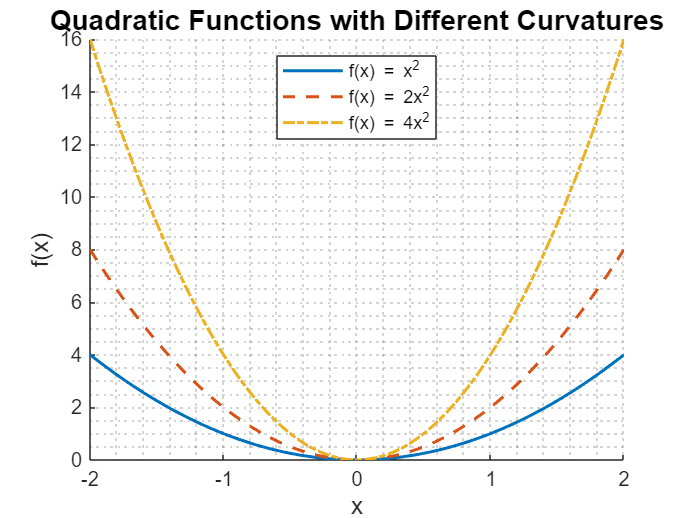

% Sample data
x = linspace(-2, 2, 100);
y1 = x.^2;
y2 = 2 * x.^2;
y3 = 4 * x.^2;

% Plot using separate commands
figure; % I opened a new figure window
hold on; % I enabled holding to plot multiple lines on the same axis

% I plotted each line with its own style
plot(x, y1, 'LineWidth', 1.5);           % Solid line for y1
plot(x, y2, '--', 'LineWidth', 1.5);    % Dashed line for y2
plot(x, y3, '-.', 'LineWidth', 1.5);    % Dash-dot line for y3

% Add grid, title, labels, and legend
grid minor;
title('Quadratic Functions with Different Curvatures', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 12);
ylabel('f(x)', 'FontSize', 12);
legend({'f(x) = x^2', 'f(x) = 2x^2', 'f(x) = 4x^2'}, 'Location', 'North'); % Legend for clarity
hold off; % I released the hold to finish plotting